# Antireset windup in PI(D) controllers

Real control systems contain nonlinearities, for example, all physical systems are subject to actuator saturation. For instance a valve actuator cannot be more than fully open or fully closed. Albeit an introductory control course focuses on the control of linear systems, nevertheless students should be aware of the effect of saturation and how this could be handled in PI(D) control of linear systems. 

When the actuator is saturated, the control loop becomes open and the saturated constant control input governs the behaviour of the process until the output of the controller returns to the linear range of the saturating element. If the controller contains an integrator, its output may "run away" (this is called integrator windup), and it could take a longer time to return to the linear range of the saturating element, if at all! This behaviour will deteriorate the performance of the control system. There are several methods to handle this situation.  

The aim of this file is to show some possibilities to avoid integrator windup, realising the so called antireset windup in case of saturation.

We assume users are familiar with the basic analysis tools such as covered in ***plotting_with_matlab.mlx, *** ***transferfunctions_and_poles.mlx, *** ***step_responses_with_matlab.mlx,  closedloop_offset_and_poles.mlx ***and also with PID controller design methods discussed in files: ***proportional_design_with_bode.mlx, lag_design_with_bode.mlx, lead_design_with_bode.mlx, lead_lag_design_with_bode_toolbox.mlx, PID_Cont_Controller_Design_with_Pole_Cancellation.mlx, PID_tuning_methods_toolbox.mlx***

This live script needs the control toolbox.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by Ruth Bars                                                           and J.A.Rossiter, University of Sheffield

Budapest University of Technology and Economics                                                 

                                 

## Table of contents

- Integrator windup in PI(D) control systems

- FOXBORO controller

- Antireset windup

- Effect of saturation in Internal Model Control

## 1. Integrator windup in PI(D) control systems

The block diagram of a control system is shown in  figure 1 below. *G* is the transfer function of the process, *M* is the transfer function of the controller. The controller is of PI or PID type. The actuator shows a saturation effect. When the control signal reaches the upper or lower limit of the actuator output, then the actuator is saturated, and the input of the process keeps this value until the output of the controller returns to the linear range of the actuator.

### 1.1 Simple integral windup with a PI controller

The figure below shows the block diagram of the simulink file (named **saturated_control_control101.slx**) using only PI controller effect. The integrator output can be shown separately.

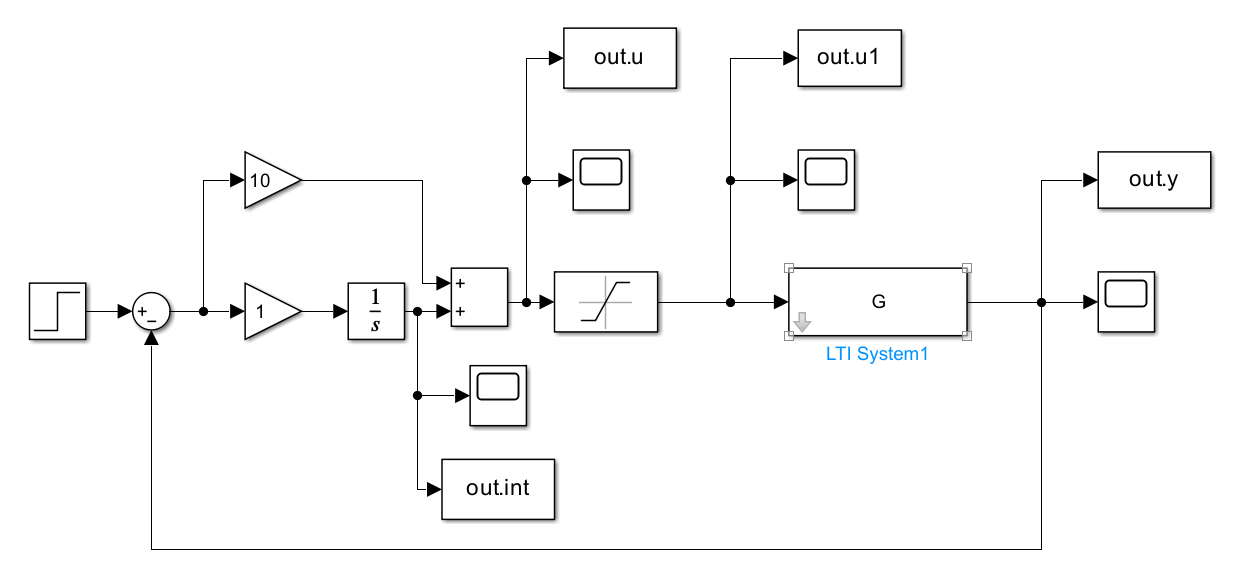

**Figure 1**: Simulink diagram of **saturated_control_control101.slx, **a system containing a saturation element

The following code illustrates a simulation of this model with particular choices of parameters; as ever the user can change these choices in order to undertake their own investigations. 

- The model of the plant is given by its transfer function: $G\left(s\right)=\frac{2}{1+10s}$. 

- The PI controller is given by: $M\left(s\right)=10\left(1+\frac{0\ldotp 1}{s}\right)$.

- The actuator contains saturation, the control signal is restricted at values +2 and -2.

In this simulation the integral winds-up to a large value and is trying to demand an input signal which is far larger than deliverable. Until the integral returns to a smaller value, the input is seen to saturate and output overshoot occurs.

disp('Section 1.1: Illustration of integral windup')

Section 1.1: Illustration of integral windup


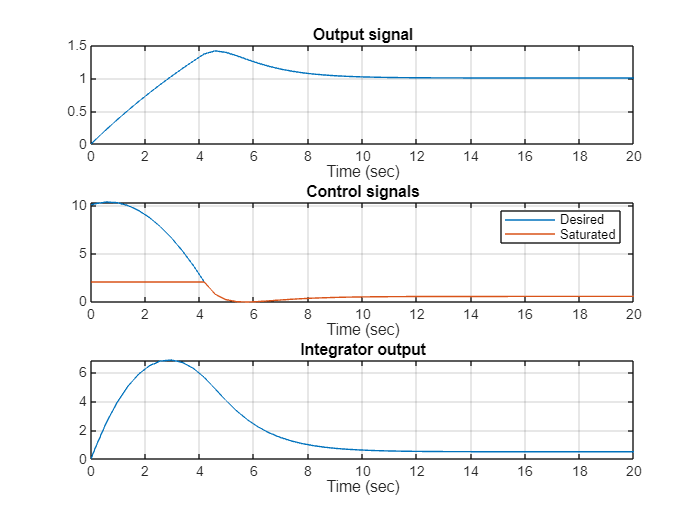

G=tf(2,[10 1]);   % model
umax=2;  % input limits
umin=-2;

% Run the Simulink simulation with the PI controller.
endtime=20;
Data=sim('saturated_control_control101.slx');
y=Data.y.signals.values;
u=Data.u.signals.values;
u1=Data.u1.signals.values;
int=Data.int.signals.values;
t = Data.u.time;


% Plotting
subplot(311)
plot(t,y),grid
title('Output signal')
xlabel('Time (sec)')

subplot(312)
plot(t,u,t,u1),grid  
legend('Desired','Saturated')
title('Control signals')
xlabel('Time (sec)')

subplot(313)
plot(t,int),grid
title('Integrator output')
xlabel('Time (sec)')

It is insightful to compare the behaviour when there are no input limits and thus no saturation. 

disp('Section 1.1: Comparison of behaviour with and without integral windup')

Section 1.1: Comparison of behaviour with and without integral windup


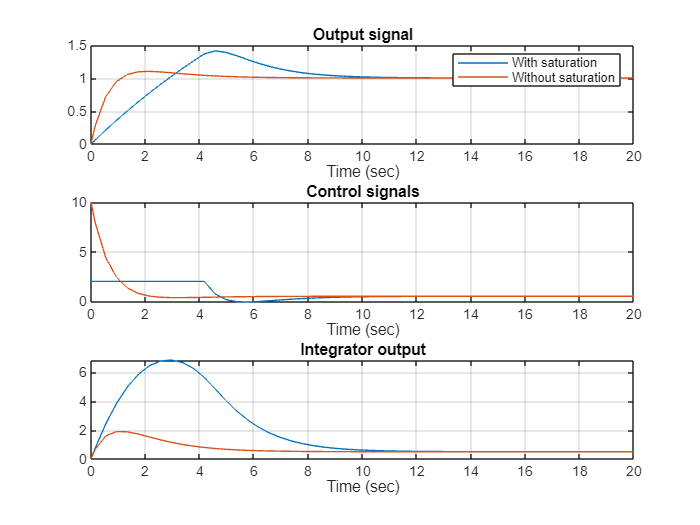

G=tf(2,[10 1]);   % modelumax=50;  % input limits
umax=50;
umin=-50;

% Run the Simulink simulation with the PI controller and no input limits.
endtime=70;
Data2=sim('saturated_control_control101.slx');
y2=Data2.y.signals.values;
u2=Data2.u.signals.values;
u12=Data2.u1.signals.values;
int2=Data2.int.signals.values;
t2 = Data2.u.time;

% Plotting
subplot(311)
plot(t,y,t2,y2),grid
title('Output signal')
legend('With saturation','Without saturation')
xlabel('Time (sec)')

subplot(312)
plot(t,u1,t2,u12),grid  
title('Control signals')
xlabel('Time (sec)')

subplot(313)
plot(t,int,t2,int2),grid
title('Integrator output')
xlabel('Time (sec)')        

### 1.2 System with integrator dynamics

Another example of how integrators and saturation can cause difficulties is shown in figure 2 below. Here the integrator dynamics occur after and not before the saturation element.

                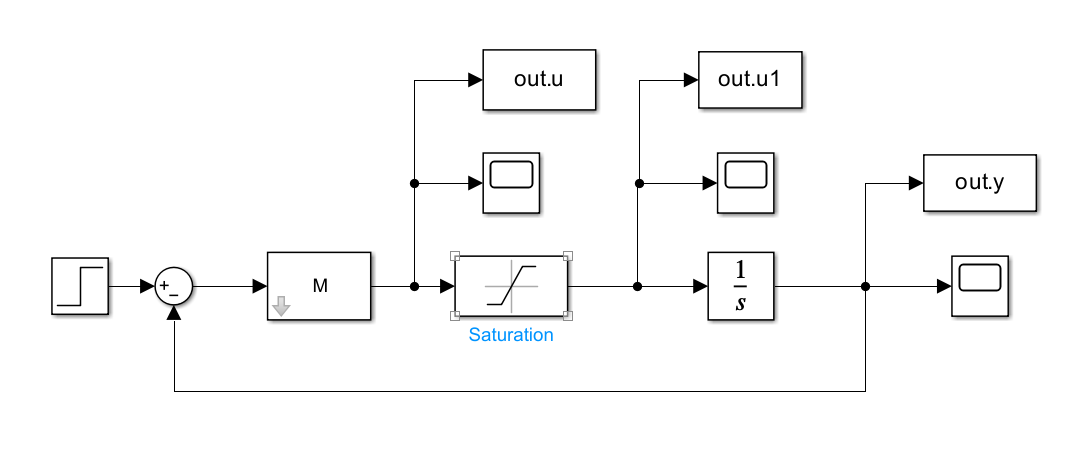

**Figure 2**: Simulink diagram of **saturatedcontrol_with_integral_control101.slx, **a system containing a saturation element

The plant is an integrator and a PI controller is designed. Its transfer function is $M\left(s\right)=\frac{6s+5}{s}$.  The closed-loop system is stable and because of the two integrators it can track  the step and the ramp reference signals with no offset and also a parabolic reference signal with a steady error.

In the simulation below the reference signal is a step function of amplitude 4. The saturation first is set to +50, -50 (effectively no saturation) and then to +2, -2.

disp('Section 1.2: behaviour when the system includes integrator dynamics')

Section 1.2: behaviour when the system includes integrator dynamics


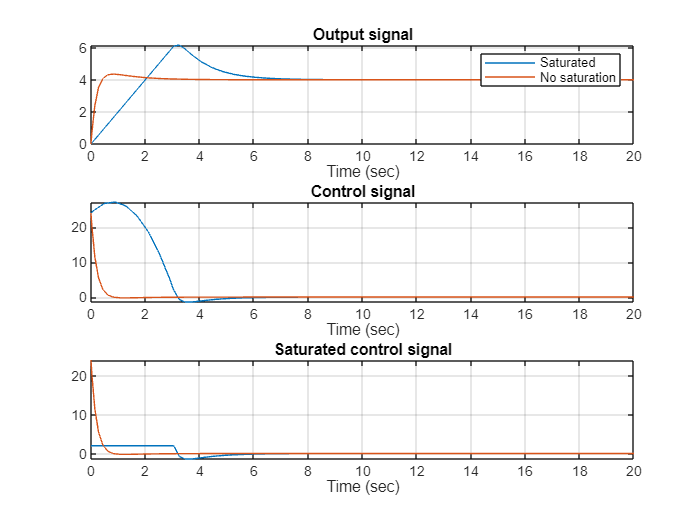


M=tf([6 5],[1 0]);

% Run the Simulink program with different saturation limits
endtime=20;
umax=2;
umin=-2;
Data=sim('saturatedcontrol_with_integral_control101.slx');
y=Data.y.signals.values;
u=Data.u.signals.values;
u1=Data.u1.signals.values;
t = Data.u.time;

umax=50;
umin=-50;
Data2=sim('saturatedcontrol_with_integral_control101.slx');
y2=Data2.y.signals.values;
u2=Data2.u.signals.values;
u12=Data2.u1.signals.values;
t2 = Data2.u.time;


% Plotting
figure; clf
subplot(311)
plot(t,y,t2,y2),grid
title('Output signal')
legend('Saturated','No saturation')
xlabel('Time (sec)')
subplot(312)
plot(t,u,t2,u2),grid  
title('Control signal')
xlabel('Time (sec)')
subplot(313)
plot(t,u1,t2,u12),grid  
title('Saturated control signal')
xlabel('Time (sec)')

It is clear that the inclusion of the saturation has led to a significant deterioration in performance.  With saturation there is a big overshoot. While the control signal is saturated, the control system works in open loop, integrating the input signal. 

There are several ways to handle this phenomenon. For example, one simple way is to prefilter the reference value to increase slowly.  

## 2. FOXBORO controller

The figure below shows the block diagram of the simulink file **foxboro_controller_control101.slx**. In this scenario, the control system with a PI controller is realised by feeding back the saturating element with a first order lag element *T* with positive feedback.

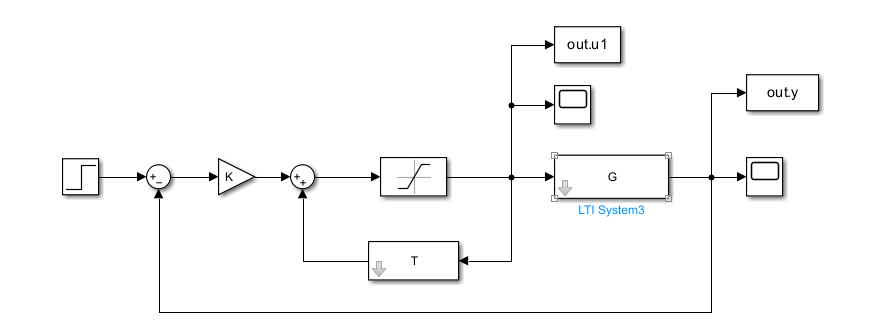

**Figure 3**: Simulink diagram of **foxboro_controller_control101.slx **implementation

The transfer function of the lag element is $T=\frac{1}{1+sT_I }$. In the linear range, the transfer function of the controller is

$M\left(s\right)=K\frac{1}{1-\frac{1}{1+sT_I }}=K\frac{1+sT_I }{sT_I }$, so it realises a PI effect, and avoids integrator windup. Let us run the file with the previous plant and controller data.

disp('Section 2: behaviour with a Foxboro approach')

Section 2: behaviour with a Foxboro approach


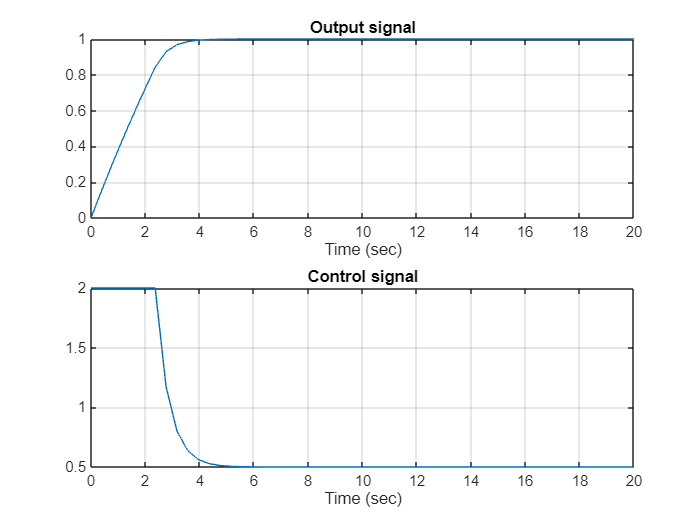


G=tf(2,[10 1]);
K=10;
Ti=10;
T=tf(1,[Ti,1]);
umax=2;  % Saturation limits
umin = -2;

% Run the Simulink simulation with the Foxboro controller.
endtime=20;
Data=sim('foxboro_controller_control101.slx');
y=Data.y.signals.values;
u1=Data.u1.signals.values;
t = Data.u1.time;

% Plotting
figure; clf
subplot(211)
plot(t,y),grid
title('Output signal')
xlabel('Time (sec)')
subplot(212)
plot(t,u1),grid  
title('Control signal')
xlabel('Time (sec)')

The figures clearly illustrate that there is no integrator windup.   

Student Task:

Try the simulation with different values of saturation.

## 3. Antireset windup

The simulink block diagram of a modified control structure suggested by K.J. Åström is shown in figure 4 below (**antiresetwindup_control101.slx**). If the output and the input of the saturation are different, the difference is fed back to the input of the controller through a constant gamma, which can be tuned by the user.

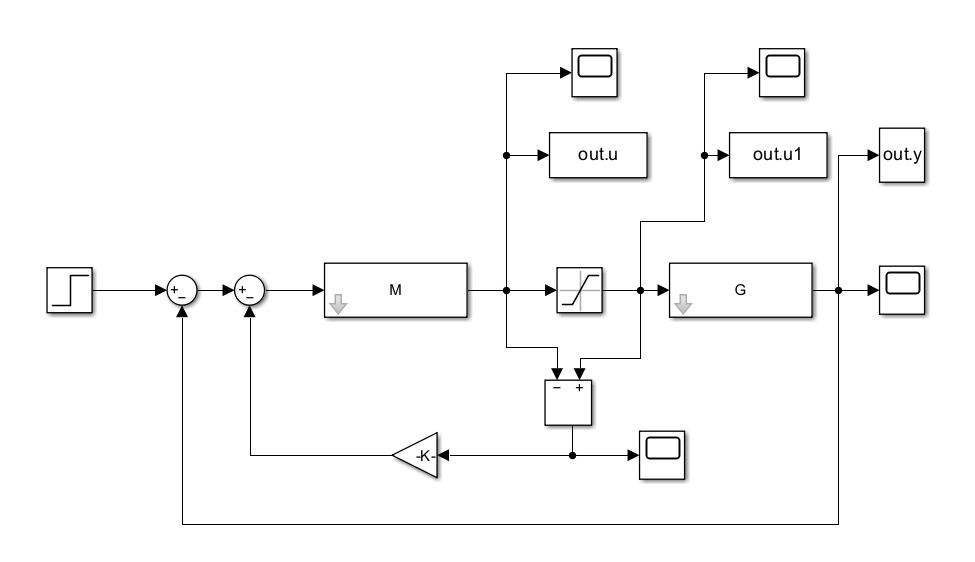

**Figure 4**: Simulink diagram of the **antiresetwindup_control101.slx **implementation

In the simulation below, the model of the plant is given by its transfer function: $G\left(s\right)=\frac{2}{1+10s}$ .   The PI controller is given by $M\left(s\right)=5\frac{1+10s}{10s}$. The actuator contains saturation, the control signal is restricted at values +2 and -2. The tuning parameter is gamma=0.5.

As with all the code, the USER is encouraged to experiment with the approach by trying different values, for example of gamma, but also for other parameters. 

REMARK: `Block diagram '`[`antiresetwindup_control101`](matlab:open_system ('antiresetwindup_control101'))`' contains 1 algebraic loop(s) which will lead to warning flags from simulink.`

disp('Section 3: behaviour with antireset windup approach')

Section 3: behaviour with antireset windup approach



G=tf(2,[10 1]);
M=tf(5*[10 1],[10 0]);
gamma=0.5; %gamma=1; gamma=5;
umin=-2; % saturation limits
umax=2;

% Run the Simulink file.
endtime=20;
Data=sim('antiresetwindup_control101.slx');

Found algebraic loop containing: 
antiresetwindup_control101/Gain
antiresetwindup_control101/Sum2
antiresetwindup_control101/LTI System/Internal
antiresetwindup_control101/Saturation (discontinuity)
antiresetwindup_control101/Add (algebraic variable)


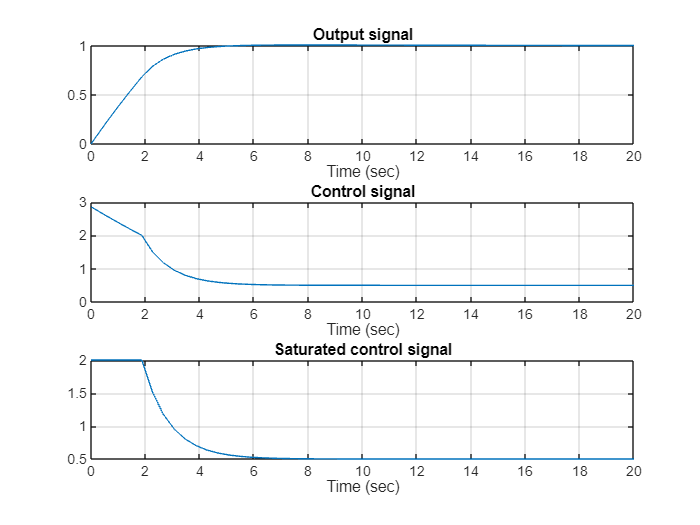

y=Data.y.signals.values;
u=Data.u.signals.values;
u1=Data.u1.signals.values;
t = Data.u.time;

% Plotting
figure;clf
subplot(311)
plot(t,y),grid
title('Output signal')
xlabel('Time (sec)')

subplot(312)
plot(t,u),grid  
title('Control signal')
xlabel('Time (sec)')

subplot(313)
plot(t,u1),grid  
title('Saturated control signal')
xlabel('Time (sec)')

## 4. Effect of saturation in Internal Model Control

In IMC (Internal Model Control) structure there is no integral windup phenomenon. The simulink diagram of the control structure is shown in figure 5 below (**IMC_saturated_control101.slx**). Here the controller is designed in open loop, it should be the inverse of the plant's transfer function, or if it is not realisable, then its good realisable approximation. The feedback works in case of plant/model mismatch, and works to eliminate the effect of the disturbance.

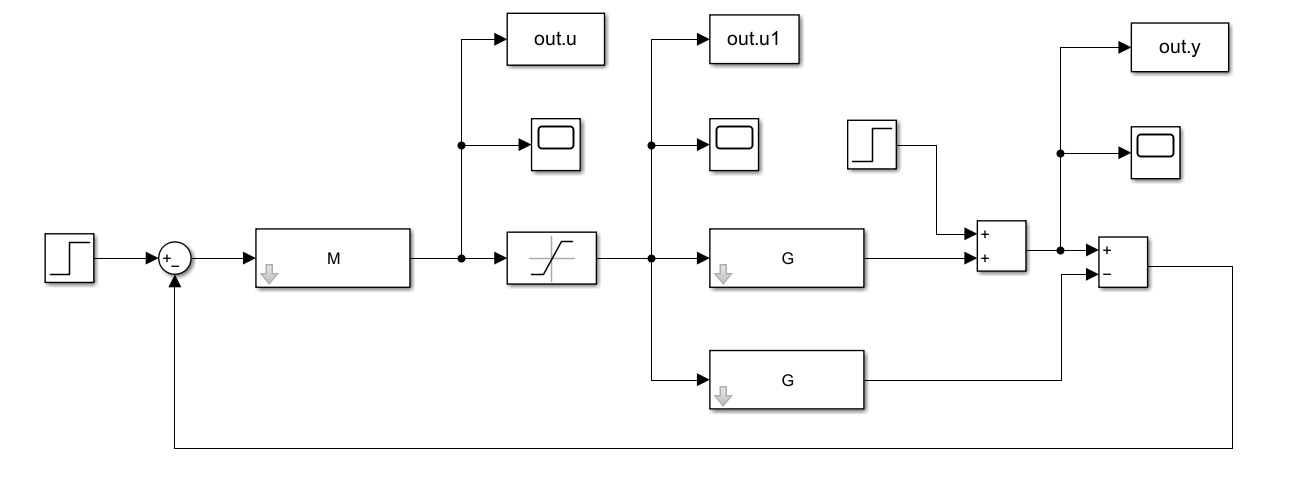

**Figure 5**: Simulink diagram of **IMC_saturated_control101.slx **implementation

For the example below, the model of the plant is given by its transfer function $G\left(s\right)=\frac{2}{1+10s}$ . The controller is given approximating the inverse of the plant's transfer function $M\left(s\right)=0\ldotp 5\frac{1+10s}{1+s}$. The actuator contains saturation, the control signal is restricted at values +2 and -2. The reference signal is a step of amplitude 1 and  a step disturbance of amplitude 0.5 acts on the output shifted by 10 sec.

As with all the code, the USER us encouraged to experiment with the approach by trying different values for the parameters. 

disp('Section 4: behaviour with an internal model control approach')

Section 4: behaviour with an internal model control approach


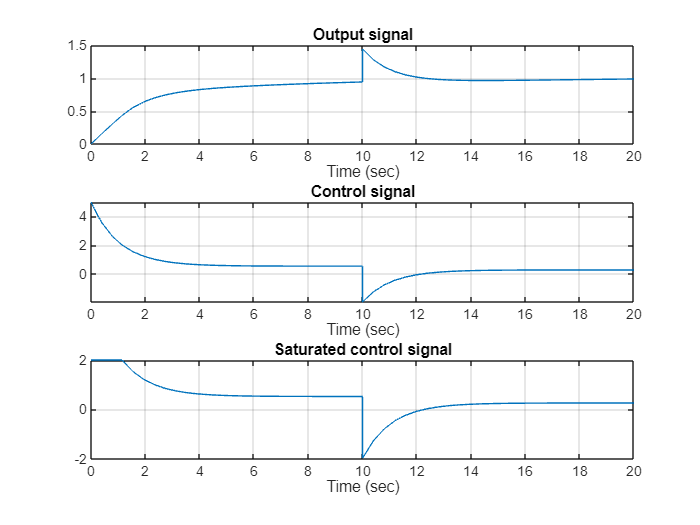


G=tf(2,[10 1]); Gm=tf(2.1,[10 1]);
M=tf(0.5*[10 1],[1 1]);
umin=-2; % saturation limits
umax=2;


% Run the Simulink simulation with the IMC controller.
endtime=20;
Data=sim('IMC_saturated_control101.slx');
y=Data.y.signals.values;
u=Data.u.signals.values;
u1=Data.u1.signals.values;
t = Data.u1.time;

% Plotting
subplot(311)
plot(t,y),grid
title('Output signal')
xlabel('Time (sec)')

subplot(312)
plot(t,u),grid  
title('Control signal')
xlabel('Time (sec)')

subplot(313)
plot(t,u1),grid  
title('Saturated control signal')
xlabel('Time (sec)')

## References

Åström, K.J., Rundquist, L.: Integrator windup and how to avoid it. American Control conference, 1989, pp. 1693-1698.

Åström, Karl J., and Tore Hägglund. *Advanced PID Control*. Triangle Park, NC: International Society of Automation, 2006.